# Universidad de Guadalajara

## Centro Universitario de Ciencias Exactas e Ingenierías

# Proyecto Final 

## Seminario de Problemas de Metodos Matematicos III

## Metodos Numéricos

# **Afinador Cromatico Temperado **

# **Utilizando la Transformada Rapida de Fourier**

## Maestro:    Rubén Sanchez Gomez

##   **  Luis Angel Muñoz Franco **

## **    Código: 303655636**

# *Introducción:*

    La transformada rapida de Fourier es una herramienta eficiente para la transformación de una señal de audio en las frecuencias que la componen con respecto a su potencia de señal.

    Teniendo esta premisa en cuenta se puede proceder a pensar en distintas aplicaciones para esta utilidad practica, entre las cuales se encuentra la que se verá en este documento.

    Para este trabajo final se pretende crear una aplicación simple que tome la señal de audio del ambiente en tiempo real, descomponiendo esta señal mediante la transformada rapida de Fourier en sus frecuencias fundamentales, resolver el problema de los armonicos naturales del sonido mediante el producto del espectro armónico, para llegar a una frecuencia fundamental y calcular la nota temperada, basado en una nota base.

Todos estos conceptos y caracteristicas se irán resolviendo y analizando a lo largo de este proyecto.

# *Definiciones:*

## *  Que es un Afinador Cromatico:*

    Es un sistema que recibe una señal de audio, la procesa descomponiendo sus notas fundamentales y comparando su frecuencia con una frecuencia base, la cual normalmente por convención es la nota La4 que se encuentra a 440hz y en el piano es la nota 49, mostrando como salida la nota musical fundamental y el error entre la nota esperada y la nota real.

## *Frecuencias de Afinación temperadas:*

Para poder crear una escala temperada es necesario en primer lugar tener una nota con una frecuencia de referencia, por convención esta nota es *'La4 (LA en su cuarta octava)' cuyo sonido* tiene una frecuencia de 440 hz. Una vez teniendo esta nota de referencia se tiene que entender lo siguiente:

-    En la musica occidental, se tienen 7 notas musicales y 5 semitonos de separación entre ellas, dando un total de 12 separaciones, estas són:

                 Las notas son: Do, Re, Mi, Fa, Sol, La, Si

                Los semitonos: Do#/Reb, Re#/Mib, Fa#/Solb, Sol#/Lab, La#,Sib

-    De acuerdo a la teoría musical cada una de las notas tiene una separación de 9 subdivisiones, sin embargo en la afinación temperada se busca separar cada nota en mitades iguales.

-    Al completar esas 12 separaciones se vuelve a la misma nota, pero una octava mas alta o mas baja respectivamente.

-    Cada octava tiene una separación del doble de frecuencia que la anterior, es decir, de la nota *La3* a *La4* hay una separación de 220 hz, mientras que de la nota *La4 *a *La5* se tiene una separación de 440hz.

      

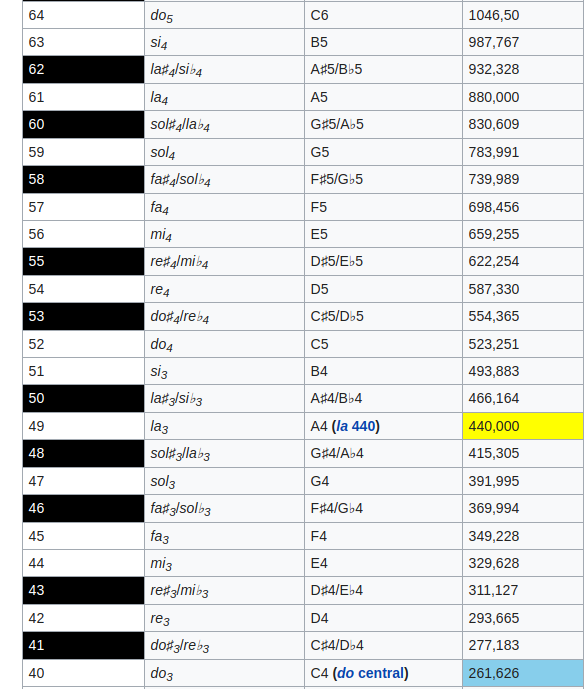

        Imagen 1- pertenece a: [https://es.wikipedia.org/wiki/Frecuencias_de_afinación_del_piano](https://es.wikipedia.org/wiki/Frecuencias_de_afinaci%C3%B3n_del_piano)

        En la imagen  anterior se puede comprobar y comparar todo lo visto con anterioridad, el numero de la nota, el nombre de la nota y la frecuencia de afinación.

    A continuación se presenta un ejemplo de una frecuencia seno reproducida a 220 Hz y 440 Hz respectivamente:

**Frecuencia 220 Hz:**

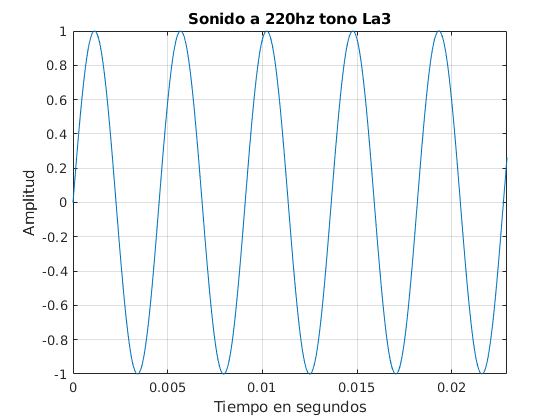

clear
Fs = 96000;    % Frecuencia de Muestreo
nBits = 24;     % Numero de Bits
nChan = 1;      % Numero de Canales

ts = 1/Fs;      % Separación
num_nota= 0:ts:1-ts;   % Arreglo de tiempo de reproducción
tono = 220;     % Tono La3
vectorAudio = sin(2*pi*tono*num_nota); %Vector de audio
player = audioplayer(vectorAudio, Fs); %creando objeto para su reproducción
play(player);   % reproducir sonido
plot(num_nota, vectorAudio);
grid on;
title("Sonido a 220 Hz tono La3");
xlabel("Tiempo en segundos");
ylabel("Amplitud");
axis([0,5*440/Fs,-1,1])

**Frecuencia a 440 Hz.**

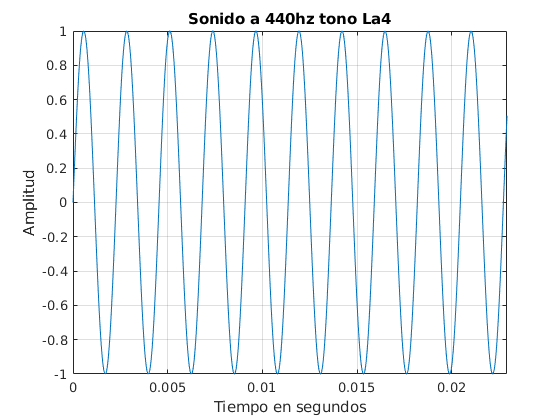

pause(1);   % pausar un segundo para reproducir lo siguiente
tono = 440;     % Tono
vectorAudio = sin(2*pi*tono*num_nota); %Vector de audio
player = audioplayer(vectorAudio, Fs); %creando objeto para su reproducción
play(player);   % reproducir sonido
plot(num_nota, vectorAudio);
grid on;
title("Sonido a 440 Hz tono La4");
xlabel("Tiempo en segundos");
ylabel("Amplitud");
axis([0,5*440/Fs,-1,1])

Como se puede observar se tiene en el mismo tiempo de reproducción dos ondas donde una es del doble de frecuencia, obteniendo con esto dos notas con una octava de separación una de otra.

- Teniendo esto en cuenta se puede obtener que el factor de la separación entre cada semitono es:


$$f=\sqrt[12]{2^n }=2^{\frac{n}{12}}$$


-   Donde **' f '** es el factor que multiplicado por una frecuencia dada obtiene la frecuencia buscada y **' n '** es el numero de semitonos positivos o negativos que se busca aumentar.

Como ejemplo se puede hacer el siguiente calculo rapido para obtener distintos semitonos partiendo de la nota La4 a 440hz con un numero de nota 49 para el piano.

frecuencia_base = 440;
f = @(aumento_semitono)(2^(aumento_semitono/12));
frecuencia_final = [];
for i = -48:39
    frecuencia_final = [frecuencia_final frecuencia_base*f(i)];
end
frecuencia_final

frecuencia_final = 	1.0e+03 *

    0.0275    0.0291    0.0309    0.0327    0.0346    0.0367    0.0389    0.0412    0.0437    0.0462    0.0490    0.0519    0.0550    0.0583    0.0617    0.0654    0.0693    0.0734    0.0778    0.0824    0.0873    0.0925    0.0980    0.1038    0.1100    0.1165    0.1235    0.1308    0.1386    0.1468    0.1556    0.1648    0.1746    0.1850    0.1960    0.2077    0.2200    0.2331    0.2469    0.2616    0.2772    0.2937    0.3111    0.3296    0.3492    0.3700    0.3920    0.4153    0.4400    0.4662


- Despejando la ecuación anterior para n, teniendo como base la frecuencia 440hz con un numero de nota 49 para el piano:


$$\begin{array}{l}
f=\sqrt[12]{2^{n-49} }=2^{\frac{n-49}{12}} \\
\mathrm{Para}\;\mathrm{obtener}\;\mathrm{la}\;\mathrm{frecuencia}\;\mathrm{final}\;\mathrm{'ff'}\;\;\mathrm{se}\;\mathrm{multiplica}\;\mathrm{la}\;\mathrm{frecuencia}\;\mathrm{base}\;\mathrm{'f'}\;\mathrm{por}\;\mathrm{el}\;\mathrm{factor}:\\
\mathrm{ff}=f\left(2^{\frac{n-49}{12}} \right)\\
\mathrm{Despejando}\;\mathrm{para}\;n:\\
\left(2^{\frac{n-49}{12}} \right)=\frac{\mathrm{ff}}{f}\\
\mathrm{log2}\left(2^{\frac{n-49}{12}} \right)=\mathrm{log2}\left(\frac{\mathrm{ff}}{f}\right)\\
\frac{n-49}{12}=\mathrm{log2}\left(\frac{\mathrm{ff}}{f}\right)\\
n-49=\mathrm{log2}\left(\frac{\mathrm{ff}}{f}\right)\left(12\right)\\
n=\mathrm{log2}\left(\frac{\mathrm{ff}}{f}\right)\left(12\right)+49
\end{array}$$


            Donde:

                        n = numero de nota temperada tomando como base la nota #49  'La4'.

                        f = nota base por convención 440hz.

                        ff = frecuencia medida.

    A continuación se pone en practica la ecuación anterior la cual ayudará a conocer el numero de nota de cierta frecuencia, donde podemos ver en la segunda fila de la matriz frecuencia final, el numero de nota que se va calculando con la frecuencia en la primer fila de la matriz.

num_nota = @(frecuencia, frecuencia_base)((log2(frecuencia/frecuencia_base)*12)+49);
for i = 1:length(frecuencia_final)
    frecuencia_final(2,i) = num_nota(frecuencia_final(1,i), frecuencia_base);
end
frecuencia_final

frecuencia_final = 	1.0e+03 *

    0.0275    0.0291    0.0309    0.0327    0.0346    0.0367    0.0389    0.0412    0.0437    0.0462    0.0490    0.0519    0.0550    0.0583    0.0617    0.0654    0.0693    0.0734    0.0778    0.0824    0.0873    0.0925    0.0980    0.1038    0.1100    0.1165    0.1235    0.1308    0.1386    0.1468    0.1556    0.1648    0.1746    0.1850    0.1960    0.2077    0.2200    0.2331    0.2469    0.2616    0.2772    0.2937    0.3111    0.3296    0.3492    0.3700    0.3920    0.4153    0.4400    0.4662
    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.04

## *Transformada Rapida de Fourier:*

    La transformada rapida de Fourier es un algorimo recursivo del tipo divide y venceras, basado en la reducción de orden y la recursividad de la Transformada Discreta de Fourier (TDF) la cual se basa en la siguiente formula:

Para K = 1, 2, 3 ..., N-1.


$$X_N \left(k\right)=\sum_{n=0}^{N-1} x\left(n\right)e^{-\frac{\mathrm{j2}\pi \mathrm{kn}}{N}}$$


Tomando la ecuación anterior y dividiendo la información en pedazos mas pequeños hasta llegar al minimo posible, el trabajo de transformación se divide en pequeños pedazos de información que son calculados de manera eficiente por la computadora.

## *        Producto del Espectro Armónico:*

    Al generar la transformada rapida de Fourier de una señal no pura,  podemos observar en la misma, frecuencias armonicas que acompañan a la frecuencia fundamental, aparte del ruido que no forma parte del sonido del cual queremos encontrar, ya que cada sonido tiene un espectro de armonicos, el cual le da el sonido particular que tiene, estos armonicos son picos en las frecuencias del sonido que no permiten a simple vista para una computadora identificar cual es la nota fundamental del sonido que estamos analizando.

    Es complicado conocer cual de los picos de la grafica de la transformada de Fourier es la nota fundamental para un programa, ya que no siempre el pico de la fundamental es el que tiene la mayor potencia de señal, por lo cual es necesario hacer un proceso adicional.

A continuación podemos ver un ejemplo de estos picos en el sonido armonico:

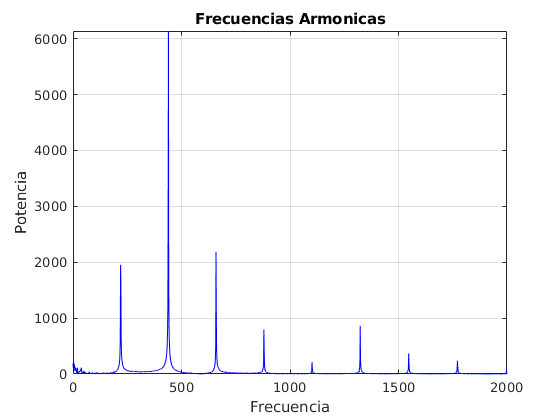

clear
Fs = 96000;
nBits = 24;
nChan = 1;
audio=audiorecorder(Fs, nBits, nChan);
pause(0.5);
record(audio);
pause(.7);
stop(audio);	
vectorAudio=getaudiodata(audio);
transformada=abs(fft(vectorAudio));
l = length(transformada);
frecuencias = linspace(0, Fs, l);
plot(frecuencias,transformada, 'b');
grid on;
title("Frecuencias Armonicas");
xlabel("Frecuencia");
ylabel("Potencia");
axis([0,2000,0,inf]);

    Para resolver este problema esta el producto del Espectro Armónico, el cual toma ventaja de las matematicas detras de estos armonicos naturales, por ejemplo:

1º armónico     66 Hz   *do*2     tono fundamental    

2º armónico     132 Hz  *do*3     octava                      Al doble de la distancia fundamental

3º armónico     198 Hz  *sol*3    quinta                       Al triple de distancia 

4º armónico     264Hz   *do*4     octava                      x4 distancia de la fundamental

5º armónico     330 Hz  *mi*4     tercera mayor           x5 distancia de la fundamental

    El producto de Espectro Armónico es la media geometrica de las amplitudes armonicas del espectro de frecuencia:

            
$$\mathrm{PEA}={\left(\Pi_{n=1}^N Y\left(\mathrm{nk}\right)\right)}^{\frac{1}{N}}$$


Donde:

N = numero de armonicos a considerar

Y = Magnitud del espectro de frecuencia

k = espacio indexado de la frecuencia especifica

A continuación se representa como funciona este proceso en codigo:

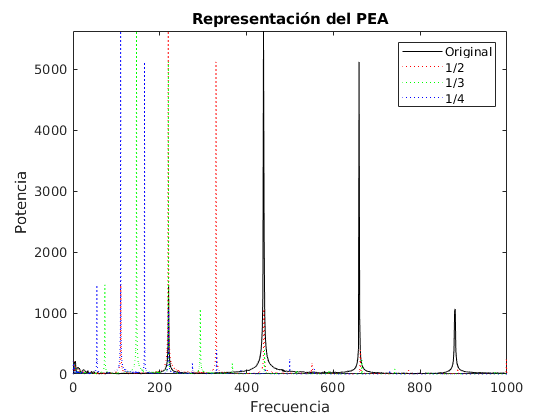

clear
nota_base = 440;
num_nota = @(frecuencia, nota_base)((log2(frecuencia/nota_base)*12)+49);
Fs = 96000;
nBits = 24;
nChan = 1;
audio=audiorecorder(Fs, nBits, nChan);
pause(0.5);
record(audio);
pause(.7); %Tiempo de reproducción del sonido
stop(audio);
vectorAudio=getaudiodata(audio);
%Transformada rapida de Fourier
transformada=abs(fft(vectorAudio));
%quitar las frecuencias debajo de 15 hz y el reflejo de la transformada que se encuentra en la segunda mitad
transformada = [ones(2,1); transformada(3:end/4)]; 
l = length(transformada);
frecuencias = linspace(0, Fs/4, l);
plot(frecuencias,transformada, 'k-', frecuencias/2,transformada, 'r:', frecuencias/3,transformada, 'g:', frecuencias/4,transformada, 'b:');
axis([0,1000,0,inf]);
title("Representación del PEA");
xlabel("Frecuencia");
ylabel("Potencia");
legend({'Original','1/2','1/3','1/4'});

En color Negro se encuentra la frecuencia original, en color Rojo la frecuencia reducida a la mitad, en color Verde una tercera parte del valor de la frecuencia y en Azul una cuarta parte de la frecuencia.

Todas las Frecuencias se unen en la frecuencia fundamental y se dispersan en las demas frecuencias.

En el siguiente codigo se calcula la media geometrica mediante un ciclo for hasta su cuarto armonico.

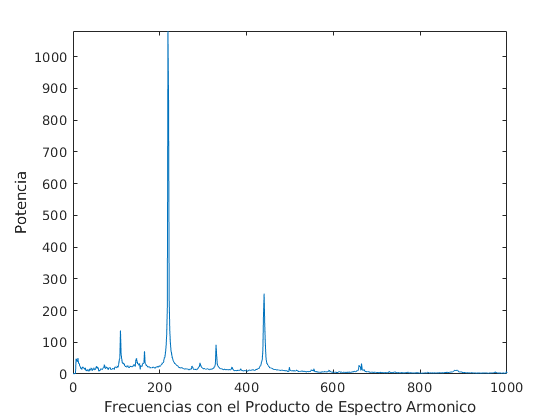

    
%calculo del producto de espectro Armónico
 magnitud_fundamental = transformada;
 armonicos = 4;
 for i =2:armonicos
     temp = [];
     for n = 1:i:(length(transformada)-i-2)
         temp = [temp; sum(transformada(n:(n+i-1),1))/i];
     end
     magnitud_fundamental = magnitud_fundamental.*([temp; ones(length(magnitud_fundamental)-length(temp),1)]);
     
 end
 magnitud_fundamental = magnitud_fundamental.^(1/armonicos);
magnitud_fundamental = [ones(5,1); magnitud_fundamental(6:end)];
plot(frecuencias,magnitud_fundamental);
axis([0,1000,0,inf]);
xlabel("Frecuencias con el Producto de Espectro Armonico");
ylabel("Potencia");

Al dispersarse las frecuencias menos en la fundamental, se obtiene el resultado esperado, ya solo quedaría sacar el valor maximo de esta ultima matriz para conocer cual es su frecuencia fundamental.

# *Desarrollo del Proyecto*

## ***Implementación del Código:***

    Con todo lo visto hasta ahora no queda mas que reunir todo el codigo y agregar unos cuantos pasos mas para tener una aplicación funcional en tiempo real.

Para comenzar limpiamos la memoria y guardamos las variables constantes que vamos a utilizar:

        1.  Limpiar memoria:

clear

        2.  Guardar una matriz con los nombres de las notas para utilizarlas mas adelante:

Estas notas comienzan con Sol# ya que la asignación de la nota se hace mediante el modulo del numero de la nota de piano sobre doce mas uno, teniendo como 49 la nota "La", mas adelante se verá el código que hace esto:

notas = ["Sol#", "La", "La#", "Si", "Do", "Do#", "Re", "Re#", "Mi", "Fa", "Fa#", "Sol"];

        3.  Guardar la frecuencia base para la nota La4, por convensión es 440hz:

nota_base = 440;

        4.  Hacer la función que tomará la frecuencia de la señal fundamental y dará como resultado el numero de nota de piano, visto anteriormente en las definiciónes:

num_nota = @(frecuencia, nota_base)((log2(frecuencia/nota_base)*12)+49);

        5.  Preparar las variables necesarias para hacer el muestreo de sonido:

-             Fs = Frecuencia de muestreo de la señal por segundo

-             nBits = Numero de Bits de la señal (8, 16, 24)

-             nChan = Numero de canales de audio, cada canal representa una fila en la matriz que se creará.

-             audio = objeto de Matlab con la configuración necesaria para guardar una señal de sonido con los parametros vistos antes.

Fs = 96000;
nBits = 24;
nChan = 1;
audio=audiorecorder(Fs, nBits, nChan);

Hacer una pausa antes de comenzar a grabar

pause(0.5);

        6.  A partir de ahora comienza un bucle que permite hacer una pequeña grabación del ambiente, hacer la transformada de fourier, sacar la nota fundamental y mostrarsela al usuario:

            **Nota- ***Para esta presentación he cambiado el bucle while por un for para evitar un bucle infinito, en la aplicación el while esta controlado por una variable 'app.start' que cambia de valor al activar un switch, de manera que puedo encender y apagar el bucle.*

% while(app.start)
for rep =1:9 %para implementarlo cambiar este for por el while que se encuentra en el renglón superior

        7.  Se hace una grabación de 70 milisegundos para tener mas detalle de la señal sin ir muy lento:

    record(audio);
    pause(.7);
    stop(audio);

        8.  Se convierte el objeto con la grabación a un vector de datos:

    vectorAudio=getaudiodata(audio);

        9.   Saco la transformada rapida de Fourier al vector de datos, tomando solo los datos reales positivos:

            Esta transformada me da un vector de magnitudes de potencia, por lo cual es necesario hacer un vector de las frecuencias de estas magnitudes mas adelante:

    transformada=abs(fft(vectorAudio));

        10. Elimino las frecuencias por debajo de los 15 hz y por arriba de los 24,000 hz, con esto tambien elimino el reflejo de la transformada que se encuentra en la segunda mitad del vector:

    transformada = [ones(2,1); transformada(3:end/4)]; 

        11. Se calcula el tamaño del vector de la transformada y se crea un vector del mismo tamaño para conocer la frecuencia del vector de la transformada:

    l = length(transformada);
    frecuencias = linspace(0, Fs/4, l);

        12. A partir de este punto se calculará el producto del espectro Armónico de acuerdo a lo visto anteriormente en la definición:

- Primero se toma una variable para guardar la matriz con las magnitudes de la transformada:

    magnitud_fundamental = transformada;

-  Ahora se hace una variable para saber cuantos armonicos va a tomar despues de la fundamental, a mi me funcionó con 4:

    armonicos = 4;

- Se hace un for para evitar repetir codigo, lo que hago es a partir del vector de la transformada ir multiplicando sus armonicos reducidos en 1/2, 1/3 y 1/4 en su frecuencia, sacando un promedio de los valores que se estan comprimiendo y asignando valores de uno en las frecuencias faltantes al comprimirse:

    for i =2:armonicos
        temp = [];
        for n = 1:i:(length(transformada)-i-2)
            temp = [temp; sum(transformada(n:(n+i-1),1))/i];
        end
        magnitud_fundamental = magnitud_fundamental.*([temp; ones(length(magnitud_fundamental)-length(temp),1)]);
    end

- Para terminar la media geometrica elevo todo a la raiz del numero de armonicos calculados:

    magnitud_fundamental = magnitud_fundamental.^(1/armonicos);

- Ya solo elimino la magnitud de las primeras 5 notas para evitar ruido inecesario en el espectro innaudible por debajo de los 20hz que pueda provocar errores en la lectura del valor maximo:

    magnitud_fundamental = [ones(5,1); magnitud_fundamental(6:end)];

        13. Tomaré el valor maximo del vector que contiene las potencias de las frecuencias, este valor maximo será la frecuencia fundamental del sonido:

                magnitud = Valor tomado como maximo del vector de potencias de la frecuencia de la señal

                indice_fundamental = indice del vector en donde se encuentra este valor maximo, el cual se utiliza para conocer mas adelante la frecuencia en ese punto

    [~, indice_fundamental] = max(magnitud_fundamental);

        14. Se toma el indice anterior para ponerlo en la matriz que guarda en esa posición su frecuencia:

    frecuencia_fundamental = frecuencias(indice_fundamental);

        15. Se usa la función creada al inicio para conocer el numero de nota del piano a partir de una frecuencia dada, pasandole como frecuencia la fundamental que acabamos de calcular:

    numero_nota = abs(num_nota(frecuencia_fundamental,nota_base));
    

        16. Para mostrar al usuario los datos de la nota se hacen los siguentes pasos:

                16.1    Se toma la parte entera redondeada de la nota del piano:

    entero_nota =round(numero_nota);

                16.2    Se toma el residuo de la nota para indicar despues al usuario que tan alejado esta del centro de la nota:

    residuo_nota = numero_nota-entero_nota;
    temperado = residuo_nota*100;

                16.3    Se calcula el modulo de la nota sobre doce mas uno y este dato se le pasa como indice al vector que indica el nombre de la nota:

    letra_nota = notas(mod(entero_nota,12)+1);

                16.4    Para saber en que octava esta la nota se toma la parte entera del numero de nota mas ocho, entre 12:

    octava = floor((entero_nota+8)/12);

                16.5    Finalmente se muestran los datos al usuario:

                    **nota.-** Para esta presentación y la aplicación de consola los datos se muestran en la consola, o en el documento respectivamente, en la app, los datos son mostrados directamente en la interfaz de usuario.

    fprintf("\n\tFrecuencia: %.2f\tNumero de Nota: %d\tNota musical: %s\tOctava: %d\t centrar: %.2f",frecuencia_fundamental, entero_nota, letra_nota, octava, temperado);
end


	Frecuencia: 220.18	Numero de Nota: 37	Nota musical: La	Octava: 3	 centrar: 1.44
	Frecuencia: 196.03	Numero de Nota: 35	Nota musical: Sol	Octava: 3	 centrar: 0.32
	Frecuencia: 174.73	Numero de Nota: 33	Nota musical: Fa	Octava: 3	 centrar: 1.11
	Frecuencia: 146.32	Numero de Nota: 30	Nota musical: Re	Octava: 3	 centrar: -6.11
	Frecuencia: 130.69	Numero de Nota: 28	Nota musical: Do	Octava: 3	 centrar: -1.63
	Frecuencia: 123.59	Numero de Nota: 27	Nota musical: Si	Octava: 2	 centrar: 1.63
	Frecuencia: 109.38	Numero de Nota: 25	Nota musical: La	Octava: 2	 centrar: -9.76
	Frecuencia: 98.15	Numero de Nota: 23	Nota musical: Sol	Octava: 2	 centrar: 2.68
	Frecuencia: 86.65	Numero de Nota: 21	Nota musical: Fa	Octava: 2	 centrar: -13.02

En este caso se puede ver la salida esperada con una entrada de escala descendente de Do mayor.

    Frecuencia: Frecuencia de sonido en Hz.

    Numero de nota: Numero de nota del piano.

    Nota musical:   Nombre de la nota en la escala musical en Español.

    Octava: Octava del sonido

    centrar: un valor negativo indica que se debe aumentar el sonido para llegar al tono, un valor positivo se debe reducir el sonido, valores por debajo de +-10 se consideran afinados.

## ***Implementación de la App para Matlab:***

Para implementar la app, utilicé la herramienta de matlab 'App Designer' la cual permite de manera simple crear un front end para el usuario, agregar componentes a la UI y tener todo ya configurado para arrastrar y pegar los componentes, fue necesario  crear una función dentro del entorno para guardar el codigo ya creado, cambiar como se acciona el bucle while con una variable global de la aplicación que cambia de valor con un callback del switch y llamar la función al momento de accionar el switch, la aplicación de matlab quedó de la siguiente manera:

**Vista Encendido                                          Apagado**

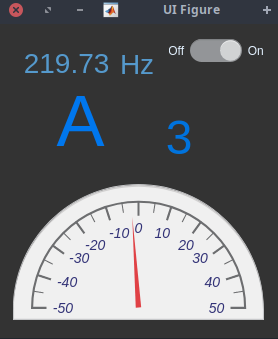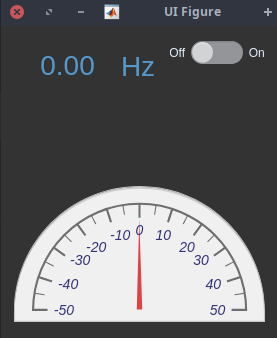

Archivo:    appTuner.mlapp

# *Conclusión:*

    Desde el inicio tuve problemas para decidirme por un proyecto, tuve varias ideas a implementar, desde la creación de una grafica interpolada en un juego de plataforma 2d, tomar los datos de los sismos en México y aplicarles la Transformada de Fourier para encontrar patrones en los periodos con que ocurren, o una aplicación similar con los datos de alguna acciión en bolsa, un autoTuner que pueda utilizar la transformada de Fourier para hacer cambios en la frecuencia y despues hacer la antitransformada para mostrar la voz con el tono cambiado, entre otras aplicaciones.

    Sin embargo, para todos estos proyectos al buscar las herramientas externas para llevarlo a cabo, como puede ser la información misma o el conocimiento sobre el tema especifico de señales que no tiene que ver intrínsecamente con los temas vistos en clase, fue complicado.

    Por lo cual al final me decidí por llevar a cabo esta aplicación practica cuyo conocimientos de Música, Matlab y Programación, la Transformada de Fourier y un poco de matematicas no fueron un impedimento para su elaboración, ademas del gusto personal por el tema musical, creo que debemos buscar crear basados en lo que nos gusta hacer, solo así se crean productos hechos con amor como se dice popularmente, productos donde se nota la pasión por lo que se hace.

    Esto no quiere decir que no tuve problemas con la implementación, desde experimentar el tiempo exacto que debía tener cada grabación, hasta el problema con los armonicos que a veces no hay como controlar, debido a que al implementar una solución para un instrumento, al probar con otro instrumento me daba otro problema...

    Para mi lo mas importante fue reafirmar que el conocimento y el entendimiento de lo que se aprende desde la raíz, es la única manera de poder utilizar y transformar lo que se sabe en alguna aplicación practica en la vida real, ya que de no conocer los fundamentos de lo aprendido, al tratar de implementar estos conocimientos en algun proyecto, nos veremos siempre con problemas practicos que requieren de 'ingeniarse' soluciones desde la base del conocimiento, conociendo la raiz de cada formula y función, saber como se crearon y como modificarlas para el uso personal.

    Es verdad que el tiempo apremia y no siempre da para conocer todas las raices de todo el conocimiento que se vé en un semestre, es necesario dedicar tiempo personal para poder verse en la tarea y necesidad de conocerlas y tambien es verdad que no siempre el alumno se encuentra con la motivación suficiente para descubrir por si mismo el conocimiento o no tiene las bases del 'aprender a aprender' buscando que todo el aprendizaje se le de 'peladito y en la boca'.

    Pero ahi es donde entra este tipo de proyectos que piden al alumno poner su conocimiento en practica, reafirmando u obligando al alumno a realmente aprender lo visto en clase mas allá de el hecho de pasar un examen, sino para poder crear algo practico con el conocimiento adquirido. Lo cual en lo personal es de lo mas motivador para aprender algo, el saber que necesito ese conocimiento para realizar algo practico y el aprender con la marcha para ver como se va realizando eso que surgió solo como una idea, es lo que motiva realmente a estudiar una 'ingeniería' o cualquier conocimiento en general.

    La aplicación creada requiere mejorar en la resolución de la frecuencia y como cualquier programa siempre estará sujeto a mejora y corrección de bugs, programación de casos especiales y demas problemas que surgen conforme se busca perfeccionar una aplicación, sin embargo como aplicación creada para el conocimiento y entendimiento de la materia, estoy satisfecho con los resultados, teniendo en cuenta que no conocía matlab antes de entrar a esta clase.

# *Bibliografía:*

*    Producto del Espectro Armónico:*

    [https://naiadseye.wordpress.com/2013/10/09/fast-fourier-transform-tuner/](https://naiadseye.wordpress.com/2013/10/09/fast-fourier-transform-tuner/) 

*    Armónicos:*

    [https://es.wikipedia.org/wiki/Armónico](https://es.wikipedia.org/wiki/Armónico) 

*    Transformada Rapida de Fourier:*

    [http://profesores.elo.utfsm.cl/~mzanartu/ELO313/Docs/ELO313_2012_FFT.pdf](http://profesores.elo.utfsm.cl/~mzanartu/ELO313/Docs/ELO313_2012_FFT.pdf)

    App Designer:

    [https://la.mathworks.com/products/matlab/app-designer.html?requestedDomain=](https://la.mathworks.com/products/matlab/app-designer.html?requestedDomain=) 

*    Frecuencias de afinación del piano temperado:*

    [https://es.wikipedia.org/wiki/Frecuencias_de_afinación_del_piano](https://es.wikipedia.org/wiki/Frecuencias_de_afinación_del_piano) 